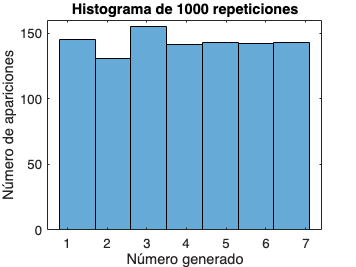

function a = aleatorios1a5()
    a = randi([1, 5]); % Genera un número entero entre 1 y 5
end

function b = aleatorios1a7()
    while true
        % Genera dos números aleatorios del 1 al 5
        num1 = aleatorios1a5();
        num2 = aleatorios1a5();
        num3 = (num1 - 1) * 5 + num2; % Resultado entre 1 y 25.
        if num3 <= 21 %Para que haya la misma probabilidad en cada uno de los 7 escogemos 21 por ser el múltiplo de 7 más cercano a 25
            % Genera un número aleatorio del 1 al 7 
            b = mod(num3 - 1, 7) + 1; 
            return;
        end
        % Si no está entre 1 y 21, vuelve al comienzo del while
    end
end

% Generamos 1000 repeticiones y las representamos en un histograma
resultados = zeros(1, 1000); 
for i = 1:1000
    resultados(i) = aleatorios1a7(); 
end

histogram(resultados, 7);
title('Histograma de 1000 repeticiones');
xlabel('Número generado');
ylabel('Número de apariciones');


%Cada valor de num1 puede ser 1, 2, 3, 4, o 5, y cada valor de num2 también puede ser 1, 2, 3, 4, o 5.
%Por lo tanto tenemos 5x5=25 valores posibles para num3.

